nCols = 60;   % samples per line (pan sweep)
nRows = [];   % number of lines (tilt steps)

B = reshape(b, nCols, nRows)';   % transpose so rows = lines, cols = samples along line
C = reshape(c, nCols, nRows)';
D = reshape(d, nCols, nRows)';

% Un-zigzag: flip every other row left-right
B(2:2:end, :) = fliplr(B(2:2:end, :));
C(2:2:end, :) = fliplr(C(2:2:end, :));
D(2:2:end, :) = fliplr(D(2:2:end, :));

imagesc(C(1,:), D(:,1), B)   % pan angles as x, tilt angles as y, data as color
colorbar
axis xy   % often needed so row 1 isn't drawn upside-down
colormap abyss
Pigeon = gca;
Pigeonpng = 'CA.png'

Pigeonpng = 'CA.png'

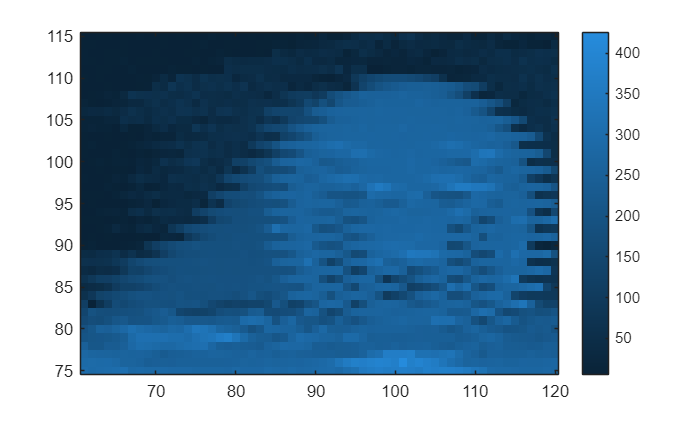

exportgraphics(Pigeon,Pigeonpng)

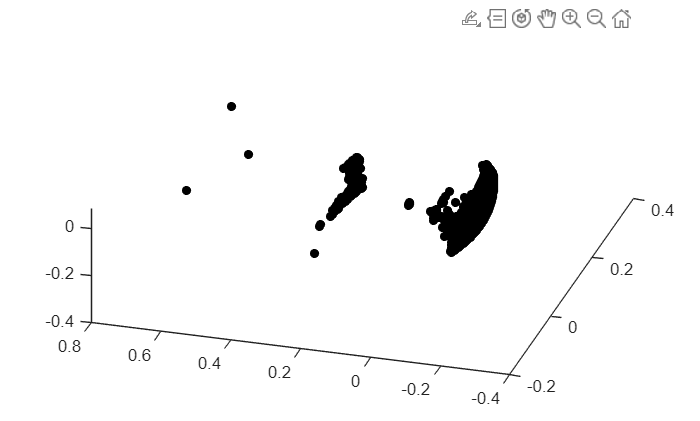

time = a;
p = 52.7016.*exp(-0.7880.*B)+(-0.2026); %
theta = deg2rad(C);%Pan angle
phi = deg2rad(D);  %Tilt angle
rho = p;

% The radial distance ρ
% 
% The azimuthal angle θ
% 
% The polar angle ϕ

% x=ρsinϕcosθ,

% y=ρsinϕsinθ,

% z=ρcosϕ.
N = length(time);
x_P = zeros(1, N);
y_P = zeros(1, N);
z_P = zeros(1, N);

for i=1:N;

x_P(i) = rho(i)*sin(phi(i))*cos(theta(i));
y_P(i) = rho(i)*sin(phi(i))*sin(theta(i));
z_P(i) = rho(i)*cos(phi(i));

end


plot3(x_P,y_P,z_P,'ko','MarkerSize',5,'MarkerFaceColor','k')